# Constant speed, straight path

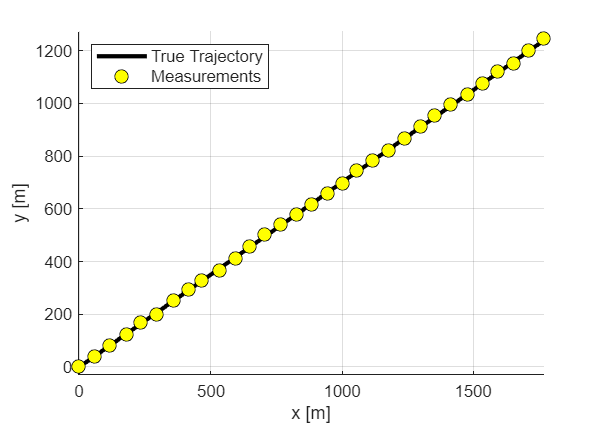

%% EKF-based Trajectory Prediction with Uncertainty Funnel
% Shows the predicted obstacle position and uncertainty bounds

clear; clc; close all;

%% Scenario Parameters
Tf          = 300;        % total duration [s]
dt_truth    = 1;        % truth propagation step [s]
dt_filter   = 1;        % filter propagation step [s]
T_meas      = 10;       % measurement interval [s]
T_pred      = 60;       % prediction horizon after each update [s]

% Ground truth motion (straight line, constant velocity)
x0_true     = 0;          % m
y0_true     = 0;          % m
v_true      = 7.2;        % m/s 
theta_true  = deg2rad(35); % rad (heading from +x)
vx_true     = v_true*cos(theta_true);
vy_true     = v_true*sin(theta_true);

% Measurement noise
sigma_xy    = 3;        % m   (position)
sigma_th    = deg2rad(2); % rad (heading)

% Process noise (acceleration spectral density -> discretized Q)
sigma_a     = 0.05;       % m/s^2 (nearly-constant-velocity model)

rng(1); % reproducible

%% Truth Trajectory
t_truth = 0:dt_truth:Tf;
N_truth = numel(t_truth);
X_true  = zeros(4, N_truth);  % [x;y;vx;vy] over time
X_true(:,1) = [x0_true; y0_true; vx_true; vy_true];

for k = 2:N_truth
    dt = dt_truth;
    F  = [1 0 dt 0;
          0 1 0  dt;
          0 0 1  0;
          0 0 0  1];
    X_true(:,k) = F * X_true(:,k-1); % perfect CV truth
end

%% Measurements
t_meas = 0:T_meas:Tf;
N_meas = numel(t_meas);

z_meas = zeros(3, N_meas); % [x; y; theta]
idx_meas_truth = round(t_meas/dt_truth) + 1;

for i = 1:N_meas
    kk = idx_meas_truth(i);
    x = X_true(1,kk); y = X_true(2,kk);
    vx = X_true(3,kk); vy = X_true(4,kk);
    th = atan2(vy, vx);
    z_meas(:,i) = [x + sigma_xy*randn;
                   y + sigma_xy*randn;
                   wrapToPi(th + sigma_th*randn)];
end

%% EKF Setup & Helpers
xhat = []; Phat = [];
R    = diag([sigma_xy^2, sigma_xy^2, sigma_th^2]);

Q_from_dt = @(dt) [ (dt^4)/4  0         (dt^3)/2  0;
                     0        (dt^4)/4  0         (dt^3)/2;
                     (dt^3)/2 0         dt^2      0;
                     0        (dt^3)/2  0         dt^2] * sigma_a^2;

F_from_dt = @(dt) [1 0 dt 0;
                   0 1 0  dt;
                   0 0 1  0;
                   0 0 0  1];

h = @(x) [x(1);
          x(2);
          atan2(x(4), x(3))];

H_jac = @(x) [1 0 0 0;
              0 1 0 0;
              0 0 -(x(4))/(x(3)^2 + x(4)^2)   x(3)/(x(3)^2 + x(4)^2)];

wrapAng = @(a) atan2(sin(a), cos(a));

t_filter = 0:dt_filter:Tf;
N_filt   = numel(t_filter);
X_filt   = nan(4, N_filt);

predictions = cell(N_meas,1);
uncertainty_bounds = cell(N_meas,1);

%% Initialize filter
x_init = z_meas(1,1);
y_init = z_meas(2,1);
dt12 = t_meas(2) - t_meas(1);
v_est = hypot(z_meas(1,2)-z_meas(1,1), z_meas(2,2)-z_meas(2,1)) / max(dt12,1e-6);
th_init = z_meas(3,2);
vx_init = v_est * cos(th_init);
vy_init = v_est * sin(th_init);
xhat = [x_init; y_init; vx_init; vy_init];
Phat = diag([sigma_xy^2*4, sigma_xy^2*4, (max(v_est,0.5))^2, (max(v_est,0.5))^2]);

%% Run EKF & Compute Uncertainty
meas_ptr = 1;
for k = 1:N_filt
    t_now = t_filter(k);

    % Predict step
    Fk = F_from_dt(dt_filter);
    Qk = Q_from_dt(dt_filter);
    xhat = Fk*xhat;
    Phat = Fk*Phat*Fk' + Qk;
    X_filt(:,k) = xhat;

    % Measurement update
    if meas_ptr <= N_meas && abs(t_now - t_meas(meas_ptr)) < 1e-9
        z = z_meas(:,meas_ptr);
        zhat = h(xhat);
        Hk   = H_jac(xhat);
        innov = z - zhat;
        innov(3) = wrapAng(innov(3));
        S = Hk*Phat*Hk' + R;
        K = Phat*Hk'/S;
        xhat = xhat + K*innov;
        Phat = (eye(4) - K*Hk)*Phat;

        % Roll out prediction with covariance
        Np = round(T_pred/dt_filter);
        x_pred = xhat;
        P_pred = Phat;
        Fp = F_from_dt(dt_filter);
        Qp = Q_from_dt(dt_filter);

        future = zeros(4, Np+1);
        P_history = zeros(4, 4, Np+1);
        future(:,1) = x_pred;
        P_history(:,:,1) = P_pred;
        
        for j = 2:Np+1
            x_pred = Fp*x_pred;
            P_pred = Fp*P_pred*Fp' + Qp;
            future(:,j) = x_pred;
            P_history(:,:,j) = P_pred;
        end

        % Compute uncertainty bounds
        n_sigma = 2;
        positions = future(1:2,:);
        upper_bound = zeros(2, Np+1);
        lower_bound = zeros(2, Np+1);
        
        for j = 1:Np+1
            P_pos = P_history(1:2,1:2,j);
            sigma_pos = sqrt(diag(P_pos)); % standard deviation in x and y
            % Uncertainty radius
            uncertainty_radius = n_sigma * norm(sigma_pos);
            
            % Store the uncertainty radius for this time step
            upper_bound(:,j) = positions(:,j) + uncertainty_radius;
            lower_bound(:,j) = positions(:,j) - uncertainty_radius;
        end

        predictions{meas_ptr} = struct('t0',t_now,'dt',dt_filter,'states',future);
        uncertainty_bounds{meas_ptr} = struct('positions', positions, ...
                                               'P_history', P_history, ...
                                               'n_sigma', n_sigma);
        meas_ptr = meas_ptr + 1;
    end
end

%% Plot 1: True Trajectory & Measurements
figure('Color','w','Position',[100 100 1000 700]);
hold on; grid on; axis equal;
xlabel('x [m]'); ylabel('y [m]');

% Plot true trajectory
plot(X_true(1,:), X_true(2,:), 'k-', 'LineWidth', 2.5, 'DisplayName', 'True Trajectory');

% Plot measurements
plot(z_meas(1,:), z_meas(2,:), 'ko', 'MarkerSize', 8, ...
     'MarkerFaceColor', 'y', 'DisplayName', 'Measurements');

legend('Location', 'northwest', 'FontSize', 10);

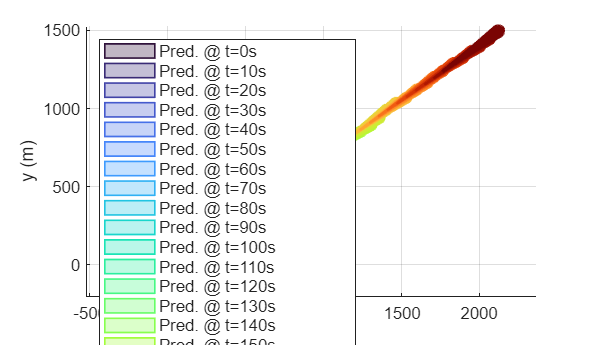


%% Plot 2: Uncertainty Funnels
figure('Color','w','Position',[150 150 1400 800]);
hold on; grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');

% Plot uncertainty funnels for each prediction
n_updates = length(predictions);
colors = turbo(n_updates);

for i = 1:n_updates
    if isempty(predictions{i}), continue; end
    
    pred_pos = predictions{i}.states(1:2,:);
    unc = uncertainty_bounds{i};
    P_hist = unc.P_history;
    n_steps = size(pred_pos, 2);
    
    % Create uncertainty ellipses at multiple points along trajectory
    ellipse_x = [];
    ellipse_y = [];
    
    for j = 1:n_steps
        P_pos = P_hist(1:2, 1:2, j);
        pos = pred_pos(:, j);
        
        % Compute ellipse
        [V, D] = eig(P_pos);
        theta_ellipse = linspace(0, 2*pi, 50);
        ellipse_pts = unc.n_sigma * sqrtm(D) * [cos(theta_ellipse); sin(theta_ellipse)];
        ellipse_pts = V * ellipse_pts;
        
        ellipse_x = [ellipse_x, pos(1) + ellipse_pts(1,:), NaN];
        ellipse_y = [ellipse_y, pos(2) + ellipse_pts(2,:), NaN];
    end
    
    % Plot the funnel
    if i == n_updates
        lw = 2;
        alpha = 0.6;
        lbl = sprintf('Final Prediction @ t=%.0fs', predictions{i}.t0);
    else
        lw = 1;
        alpha = 0.3;
        lbl = sprintf('Pred. @ t=%.0fs', predictions{i}.t0);
    end
    
    patch(ellipse_x, ellipse_y, colors(i,:), 'FaceAlpha', alpha, ...
          'EdgeColor', colors(i,:), 'LineWidth', lw, 'DisplayName', lbl);
    
    % Plot predicted centerline
    plot(pred_pos(1,:), pred_pos(2,:), '--', 'Color', colors(i,:), ...
         'LineWidth', 1.5, 'HandleVisibility', 'off');
end

legend('Location', 'northwest', 'FontSize', 10);


%% Console Stats
fprintf('=== Uncertainty Funnel Analysis ===\n');

=== Uncertainty Funnel Analysis ===


fprintf('Confidence level: %.1f-sigma (%.1f%%)\n', n_sigma, 100*erf(n_sigma/sqrt(2)));

Confidence level: 2.0-sigma (95.4%)


fprintf('Prediction horizon: %.0f s\n', T_pred);

Prediction horizon: 60 s


fprintf('Measurement interval: %.0f s\n', T_meas);

Measurement interval: 10 s


fprintf('\nNumber of prediction updates: %d\n', n_updates);


Number of prediction updates: 31



% Analyze final prediction
if ~isempty(uncertainty_bounds{end})
    final_unc = uncertainty_bounds{end};
    final_P = final_unc.P_history(:,:,end);
    final_sigma_xy = sqrt(diag(final_P(1:2,1:2)));
    final_total_uncertainty = n_sigma * norm(final_sigma_xy);
    
    fprintf('\nFinal prediction (at t=%.0fs, looking %.0fs ahead):\n', ...
            predictions{end}.t0, T_pred);
    fprintf('  Position uncertainty (%.0fσ): x=±%.2fm, y=±%.2fm\n', ...
        n_sigma, n_sigma*final_sigma_xy(1), n_sigma*final_sigma_xy(2));
    fprintf('  Total uncertainty radius: %.2f m\n', final_total_uncertainty);
    fprintf('  Velocity uncertainty (%.0fσ): vx=±%.3fm/s, vy=±%.3fm/s\n', ...
        n_sigma, n_sigma*sqrt(final_P(3,3)), n_sigma*sqrt(final_P(4,4)));
end


Final prediction (at t=300s, looking 60s ahead):


  Position uncertainty (2σ): x=±36.51m, y=±35.02m


  Total uncertainty radius: 50.59 m


  Velocity uncertainty (2σ): vx=±0.856m/s, vy=±0.842m/s
